close all
clear
clc

定义系统

a = [1, -0.5, 0.6];
b = [1, 0, -0.3];

定义仿真时刻

n = [0:20]';

用impz函数计算单位样值响应

[hi, t] = impz(b,a,n);

按定义生成单位样值序列，用滤波计算单位样值响应

x = (n == 0);
hf = filter(b,a,x);

绘图，验证两者相同

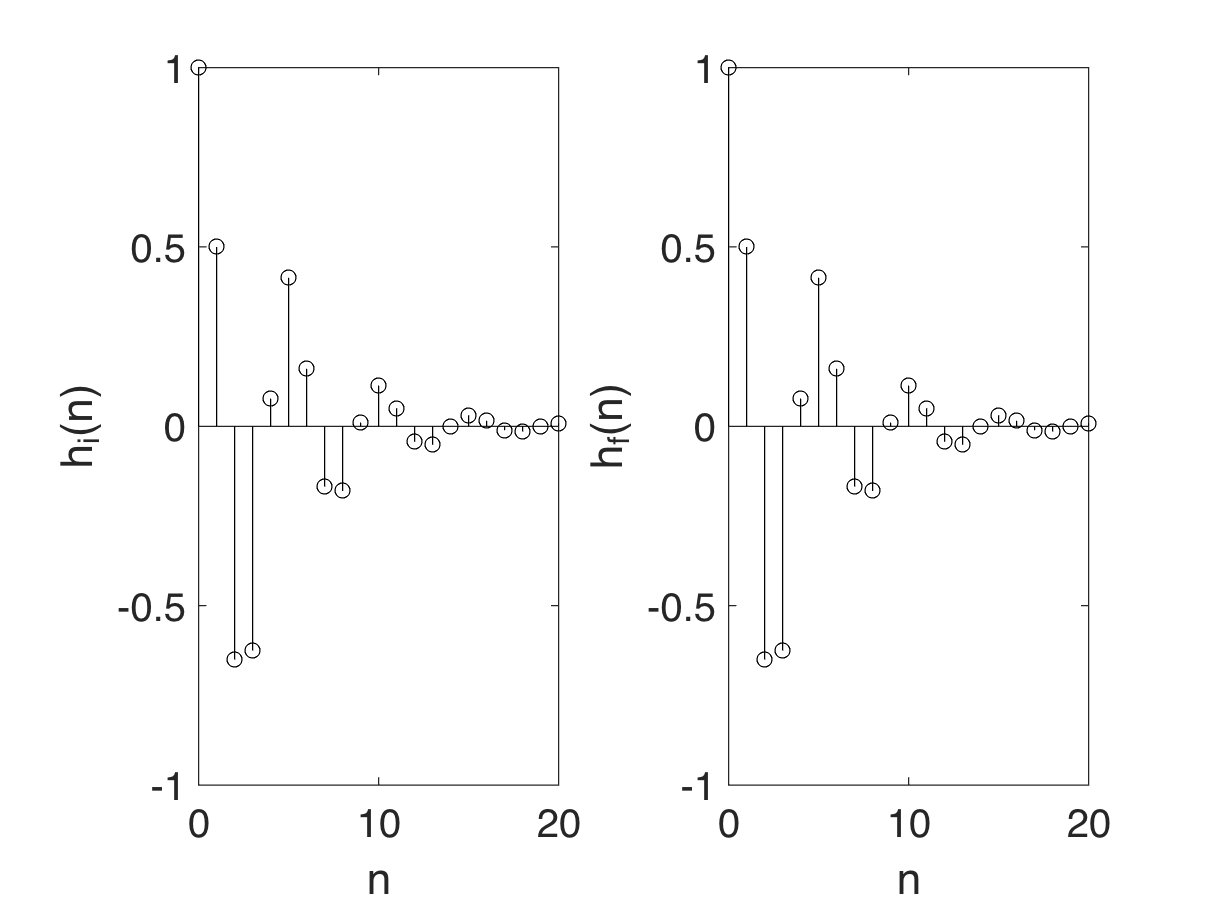

figure;
subplot(1,2,1), hold on, box on;
stem(n,hi,'k-');
set(gca,'YScale','linear','FontSize',16);
xlabel('n');
ylabel('h_i(n)');
subplot(1,2,2), hold on, box on;
stem(n,hf,'k-');
set(gca,'YScale','linear','FontSize',16);
xlabel('n');
ylabel('h_f(n)');